% low pass filter in frequency domain
K=500;
k=-K:K;
N=41;
n=0:2*50;
w=k*pi/K

w =    -3.1416   -3.1353   -3.1290   -3.1227   -3.1165   -3.1102   -3.1039   -3.0976   -3.0913   -3.0850   -3.0788   -3.0725   -3.0662   -3.0599   -3.0536   -3.0473   -3.0411   -3.0348   -3.0285   -3.0222   -3.0159   -3.0096   -3.0034   -2.9971   -2.9908   -2.9845   -2.9782   -2.9719   -2.9657   -2.9594   -2.9531   -2.9468   -2.9405   -2.9342   -2.9280   -2.9217   -2.9154   -2.9091   -2.9028   -2.8965   -2.8903   -2.8840   -2.8777   -2.8714   -2.8651   -2.8588   -2.8526   -2.8463   -2.8400   -2.8337


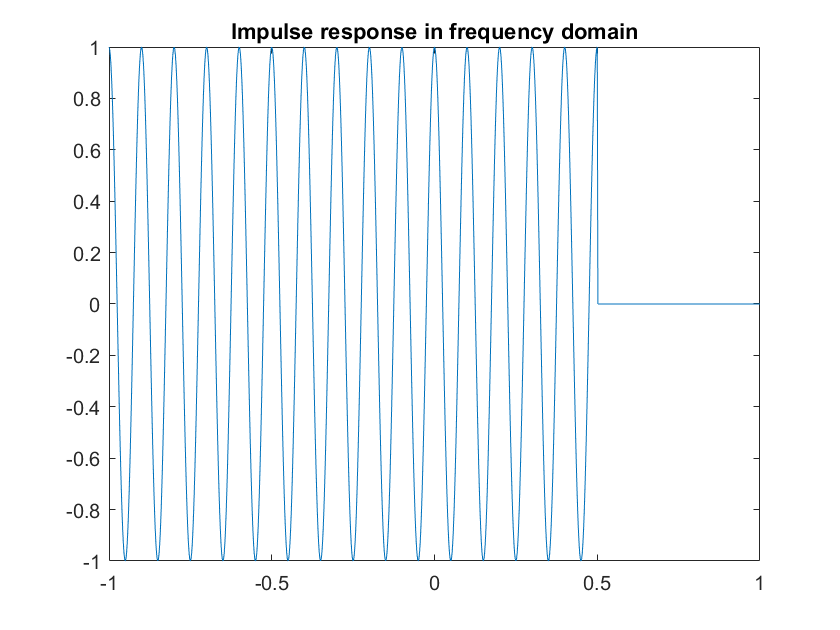

Hd=w;
% prb 3.8.1
a=20;
wc=0.5*pi;
for i=1:length(w)
    if w(i)<=wc
        Hd(i)=exp(-1j*a*w(i));
    else
        Hd(i)=0;
    end
end
figure("Name",'DTFT')
plot(w/pi,real(Hd))
title('Impulse response in frequency domain')

[hd,n]=idtft(Hd,n,w)

hd =    0.0010 + 0.0000i  -0.0089 + 0.0089i  -0.0000 - 0.0177i   0.0089 + 0.0089i   0.0010 + 0.0000i  -0.0111 + 0.0111i   0.0000 - 0.0227i   0.0117 + 0.0117i   0.0010 - 0.0000i  -0.0150 + 0.0150i   0.0000 - 0.0318i   0.0172 + 0.0172i   0.0010 + 0.0000i  -0.0232 + 0.0232i   0.0000 - 0.0530i   0.0313 + 0.0313i   0.0010 + 0.0000i  -0.0536 + 0.0536i  -0.0000 - 0.1592i   0.1587 + 0.1587i   0.7510 + 0.0000i   0.1587 - 0.1587i   0.0000 + 0.1592i  -0.0536 - 0.0536i   0.0010 + 0.0000i   0.0313 - 0.0313i  -0.0000 + 0.0530i  -0.0232 - 0.0232i   0.0010 - 0.0000i   0.0172 - 0.0172i  -0.0000 + 0.0318i  -0.0150 - 0.0150i   0.0010 - 0.0000i   0.0117 - 0.0117i   0.0000 + 0.0227i  -0.0111 - 0.0111i   0.0010 - 0.0000i   0.0089 - 0.0089i   0.0000 + 0.0177i  -0.0089 - 0.0089i   0.0010 - 0.0000i   0.0071 - 0.0071i  -0.0000 + 0.0144i  -0.0074 - 0.0074i   0.0010 + 0.0000i   0.0059 - 0.0059i  -0.0000 + 0.0122i  -0.0064 - 0.0064i   0.0010 - 0.0000i   0.0050 - 0.0050i


n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


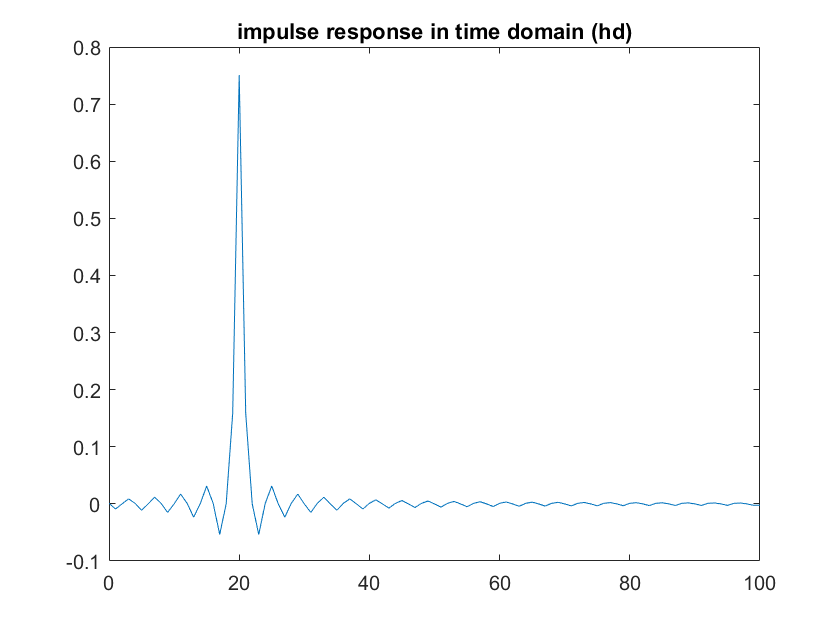

figure("Name",'IDTFT')
plot(n,real(hd))
title('impulse response in time domain (hd)')

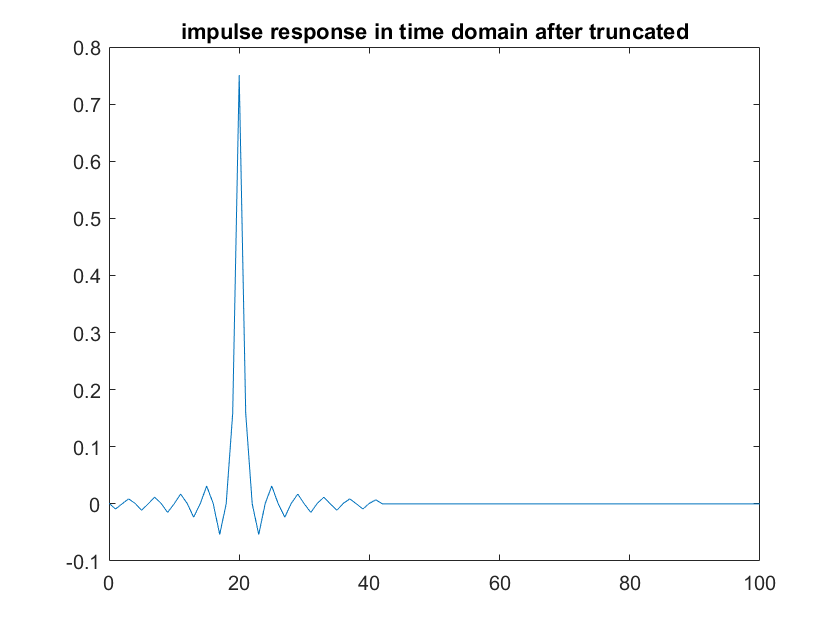

% end prb 3.8.1
% start prb 3.8.2
h=hd;
for i=1:length(n)
    if n(i)>N
        h(i)=0;
    end
end
figure("Name",'IDTFT')
plot(n,real(h))
title('impulse response in time domain after truncated')

% end prb 3.8.2
% start prb 3.8.3
[H,w]=dtft(h,n,w)

H =    0.5219 + 0.0071i   0.5593 - 0.0627i   0.5865 - 0.1416i   0.6015 - 0.2282i   0.6026 - 0.3203i   0.5888 - 0.4155i   0.5591 - 0.5113i   0.5132 - 0.6048i   0.4514 - 0.6932i   0.3743 - 0.7738i   0.2832 - 0.8438i   0.1798 - 0.9007i   0.0663 - 0.9426i  -0.0549 - 0.9675i  -0.1809 - 0.9744i  -0.3089 - 0.9625i  -0.4356 - 0.9314i  -0.5581 - 0.8815i  -0.6733 - 0.8136i  -0.7786 - 0.7291i  -0.8714 - 0.6296i  -0.9495 - 0.5174i  -1.0112 - 0.3948i  -1.0552 - 0.2645i  -1.0807 - 0.1292i  -1.0873 + 0.0081i  -1.0750 + 0.1447i  -1.0443 + 0.2778i  -0.9963 + 0.4049i  -0.9322 + 0.5238i  -0.8534 + 0.6324i  -0.7619 + 0.7290i  -0.6595 + 0.8122i  -0.5483 + 0.8809i  -0.4303 + 0.9344i  -0.3078 + 0.9723i  -0.1828 + 0.9945i  -0.0572 + 1.0011i   0.0671 + 0.9923i   0.1883 + 0.9689i   0.3049 + 0.9313i   0.4154 + 0.8806i   0.5183 + 0.8176i   0.6127 + 0.7433i   0.6973 + 0.6589i   0.7712 + 0.5655i   0.8335 + 0.4644i   0.8836 + 0.3568i   0.9207 + 0.2440i   0.9443 + 0.1276i


w =    -3.1416   -3.1353   -3.1290   -3.1227   -3.1165   -3.1102   -3.1039   -3.0976   -3.0913   -3.0850   -3.0788   -3.0725   -3.0662   -3.0599   -3.0536   -3.0473   -3.0411   -3.0348   -3.0285   -3.0222   -3.0159   -3.0096   -3.0034   -2.9971   -2.9908   -2.9845   -2.9782   -2.9719   -2.9657   -2.9594   -2.9531   -2.9468   -2.9405   -2.9342   -2.9280   -2.9217   -2.9154   -2.9091   -2.9028   -2.8965   -2.8903   -2.8840   -2.8777   -2.8714   -2.8651   -2.8588   -2.8526   -2.8463   -2.8400   -2.8337


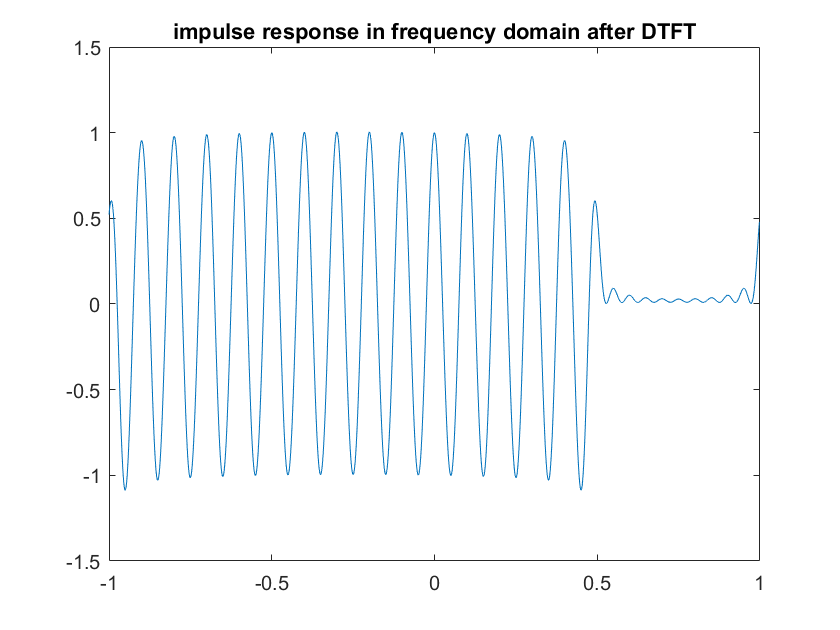

figure("Name",'DTFT of signal h')
plot(w/pi,real(H))
title('impulse response in frequency domain after DTFT')

%comment about the observation of H and Hd
% here i see some noise after cutoff frequency in H signal and maximu error
% is 0.4781
error=(max(abs(real(Hd)-real(H)))),%/max(real(h))

error = 0.4781

% end prb 3.8.3
% h=movmean(h,5)
% figure("Name",' IDTFT after mm')
% plot(n,real(h))
% title('impulse response in time domain after mm')
% 
% h=spline(n*(1/1),h,n)
% figure("Name",'IDTFT after spline')
% plot(n,real(h))
% title('impulse response in time domain after spline')
